%Fecha de actualización: 21/oct/2023
%V 0.0.1
%clc
%clear all

# Practica 002: Curso de MATLAB para ingeniería

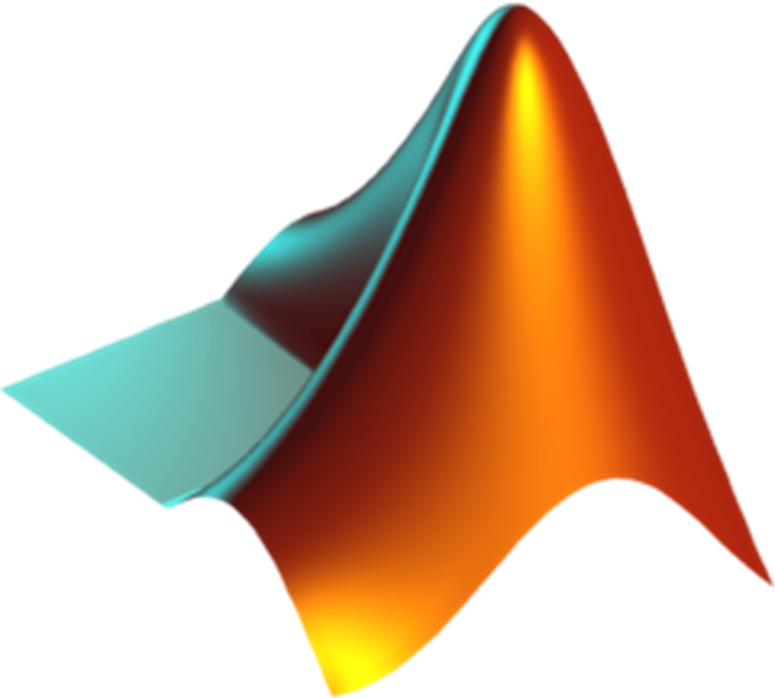

## Contenedores de datos

En MATLAB, los contenedores de datos se refieren a las estructuras de datos que permiten almacenar y organizar la información de manera eficiente. Los contenedores más comunes son las matrices numéricas, las tablas y las celdas

### Matrices numéricas (arrays numéricos)

En términos matemáticos, una matriz se refiere a un arreglo de números en forma rectangular. Estos números que forman la matriz se llaman entradas o elementos y se anotan dentro de paréntesis. Cuando uno se refiere al conjunto de números ubicados en las líneas horizontales estas se conocen como filas, mientras que aquellos números verticales serán conocidos como columnas.

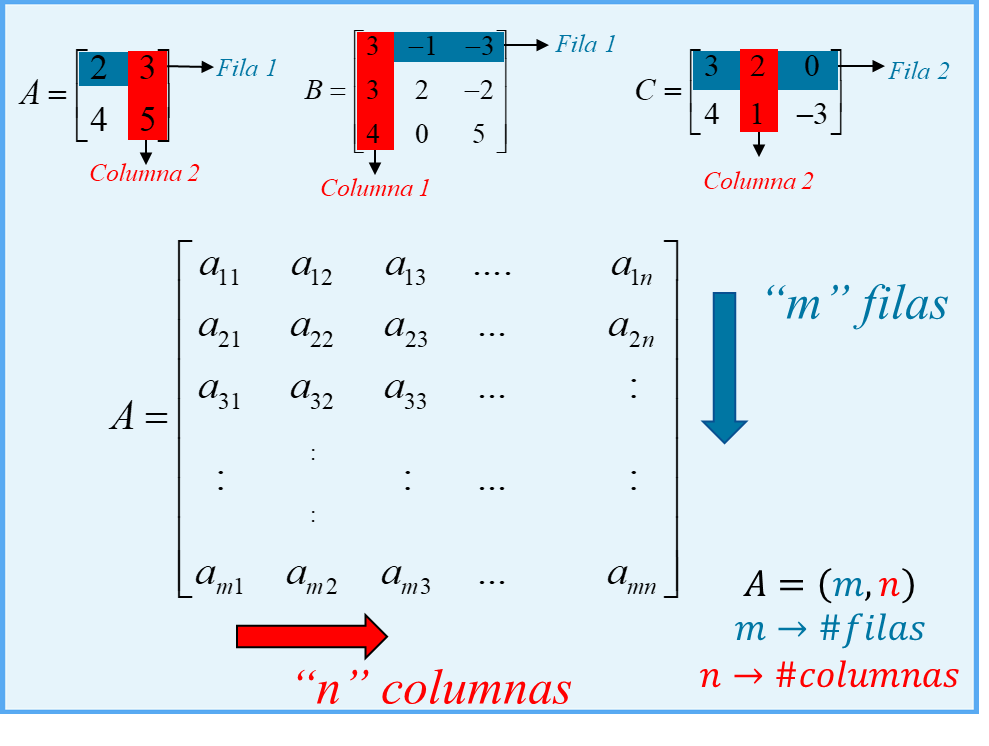

%Para definir un valor escalar en matlab, bastará con describir el objeto
%en el workspace y asignarle el valor deseado

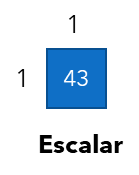

escalar = 3;
disp(escalar)

     3



%Por su parte, podemos declarar un vector fila o un vector columna de la
%siguiente manera

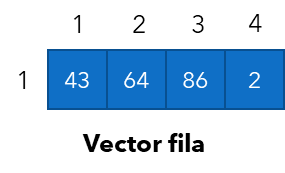

%Vector fila
 vectorF = [1, 2, 3, 4];
 disp(vectorF)

     1     2     3     4


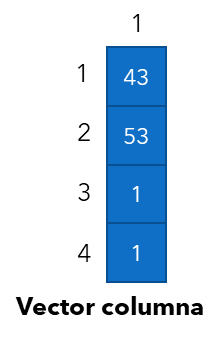

%vector columna
 vectorC = [1; 2; 3; 4];
 disp(vectorC)

     1
     2
     3
     4


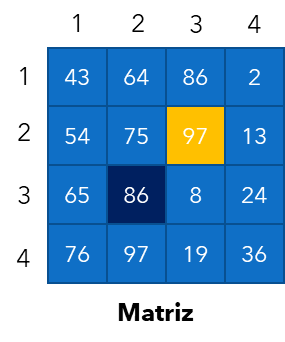

%Además de esto, una matriz la podemos declarar en matlab como una
%combinacion de vectores fila y columna de la siguiente manera
matriz =[1, 2, 3, 4; 5, 6, 7, 8; 9, 10, 11, 12; 13, 14, 15, 16];
disp(matriz)

     1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16


En MATLAB, el termino de "tensor" generalmente se utiliza para referirse a arreglos multidimensionales. En otras palabras, un tensor en MATLAB es simplemente un arreglo que puede tener mas de dos dimensiones. Por ejemplo considera un tensor cuatridimensional de la siguiente manera

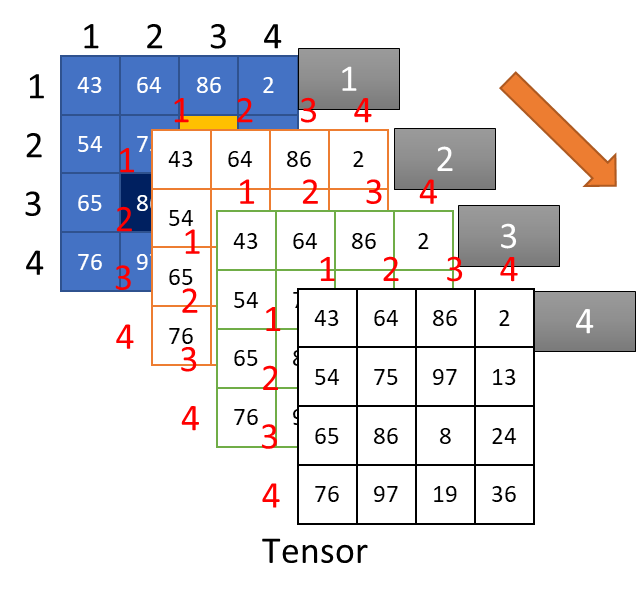

tensor(:,:,1) = [  1,  2;  3,  4];
tensor(:,:,2) = [  5,  6;  7,  8];
tensor(:,:,3) = [  9, 10; 11, 12];
tensor(:,:,4) = [ 13, 14; 15, 16];
disp(tensor)

(:,:,1) =
     1     2
     3     4
(:,:,2) =
     5     6
     7     8
(:,:,3) =
     9    10
    11    12
(:,:,4) =
    13    14
    15    16


#### Acceso con índices

En MATLAB, el acceso a los elementos de un arreglo se realiza utilizando índices. La forma de acceder a un elemento específico depende de la dimensionalidad del arreglo. 

Se declara la variable donde se almacenará el valor seguido del valor de fila y columna

%Declaramos una matriz de valores cualesquiera

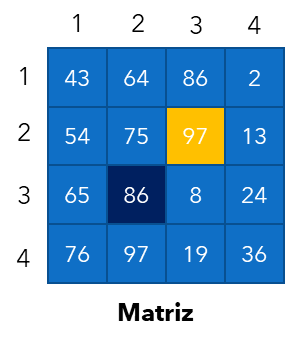

matriz = [43,64,86,2; 54,75,97,13; 65,86,8,24;76,97,19,36];
disp(matriz)

    43    64    86     2
    54    75    97    13
    65    86     8    24
    76    97    19    36



%extraemos el valor de la casilla amarilla
amarillo = matriz(2,3);
disp(amarillo)

    97



%El cual es distinto al de la casilla azul rey
azulRey = matriz(3,2);
disp(azulRey)

    86


#### Extracción de datos en rangos de valores

A = matriz(2:3, 1:4);
disp(A)

    54    75    97    13
    65    86     8    24


B = matriz(:,2);
disp(B)

    64
    75
    86
    97


#### Operaciones de matrices

matriz(1,2) = sqrt(matriz(1,2))

matriz =     43     8    86     2
    54    75    97    13
    65    86     8    24
    76    97    19    36


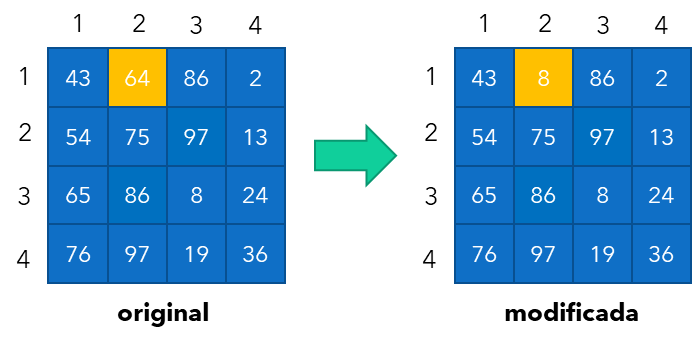

%Se declaran dos matrices ejemplo
A = [1,2;3,4];
B = [5,6;7,8];
C = [10,20;30,40];

**Suma y resta de matrices**

suma = A + C;
disp(suma)

    11    22
    33    44


resta = A - C;
disp(resta)

    -9   -18
   -27   -36


**Multiplicacion de matrices**

multiplicacion = A * B;
disp(multiplicacion)

    19    22
    43    50


**Multiplicacion elemento a elemento**

multiplicacionEaE = A.*C;
disp(multiplicacionEaE)

    10    40
    90   160


Las operaciones denominadas como elemento a elemento o "Element-wise", se realizan tomando cada elemento de la matriz y realizando la operacion con el mismo elemento de la segunda matriz. Estas operaciones se denotan con un punto antes del operador. Esto e fundamental cuando se trabaja con matrices y se quiere operar de manera independiente cada elemento.

Recuerda que para realizar las operaciones de matrices, las dimensiones de estas deben de coincidir de manera adecuada. Por ejemplo en la multiplicacion de matrices, el numero de columnas en la primera matriz debe ser ifual al numero de filas en la segunda matriz

### Tablas de datos

Una `table` (tabla) es un tipo de dato adecuado para datos orientados a columnas o datos tabulares que suelen almacenarse como columnas en un archivo de texto o en una hoja de cálculo. Las tablas constan de filas y variables orientadas a columnas. Cada variable en una tabla puede tener un tipo de datos y un tamaño diferente, con la única restricción de que cada variable debe tener la misma cantidad de filas. 

% Crear una tabla de datos de estudiantes
nombres = {'Ana', 'Carlos', 'Eva', 'Juan', 'María'};
edades = [22; 20; 21; 23; 22];
calificaciones = [85, 92, 78, 89, 95];

% Crear la tabla (con transposición de 'nombres')
tablaEstudiantes = table(nombres', edades, calificaciones', 'VariableNames', {'Nombre', 'Edad', 'Calificacion'});

% Mostrar la tabla
disp(tablaEstudiantes);

      Nombre      Edad    Calificacion
    __________    ____    ____________
    {'Ana'   }     22          85     
    {'Carlos'}     20          92     
    {'Eva'   }     21          78     
    {'Juan'  }     23          89     
    {'María' }     22          95     



% Acceder a datos específicos en la tabla
edadJuan = tablaEstudiantes.Edad(strcmp(tablaEstudiantes.Nombre, 'Juan'));
disp(['La edad de Juan es: ' num2str(edadJuan)]);

La edad de Juan es: 23



% Calcular la calificación promedio
promedioCalificaciones = mean(tablaEstudiantes.Calificacion);
disp(['La calificación promedio es: ' num2str(promedioCalificaciones)]);

La calificación promedio es: 87.8


### Estructuras de datos

Un arreglo de estructura es un tipo de dato que agrupa datos relacionados mediante contenedores de datos llamados campos. Cada campo puede contener cualquier tipo de datos. Para acceder a los datos de una estructura, es posible usar una notación punto con el formato `structName.fieldName`.

% Crear estructuras para representar información sobre estudiantes
estudiante1.nombre = 'Ana';
estudiante1.edad = 22;
estudiante1.calificacion = 85;

estudiante2.nombre = 'Carlos';
estudiante2.edad = 20;
estudiante2.calificacion = 92;

estudiante3.nombre = 'Eva';
estudiante3.edad = 21;
estudiante3.calificacion = 78;

% Almacenar las estructuras en un arreglo
estudiantes = [estudiante1, estudiante2, estudiante3];

% Mostrar información de estudiantes
for i = 1:length(estudiantes)
    fprintf('Nombre: %s\n', estudiantes(i).nombre);
    fprintf('Edad: %d\n', estudiantes(i).edad);
    fprintf('Calificación: %d\n', estudiantes(i).calificacion);
    fprintf('\n');
end

Nombre: Ana


Edad: 22


Calificación: 85


Nombre: Carlos


Edad: 20


Calificación: 92


Nombre: Eva


Edad: 21


Calificación: 78



% Calcular la calificación promedio
calificaciones = [estudiantes.calificacion];
promedioCalificaciones = mean(calificaciones);
disp(['La calificación promedio es: ' num2str(promedioCalificaciones)]);

La calificación promedio es: 85


### Arreglos de celdas

Un arreglo de celdas es un tipo de dato con contenedores de datos indexados llamados celdas, donde cada celda puede contener cualquier tipo de datos. Los arreglos de celdas son útiles para datos no tabulares a los que desea acceder por índice numérico. 

% Crear una celda de datos de libros
libro1 = {'El señor de los anillos', 'J.R.R. Tolkien', 9788445073806, 'Fantasía', 25.99};
libro2 = {'Cien años de soledad', 'Gabriel García Márquez', 9780307474728, 'Realismo mágico', 19.99};
libro3 = {'1984', 'George Orwell', 9780451524935, 'Distopía', 15.99};

% Crear una celda que contiene los datos de los libros
celdaLibros = {libro1; libro2; libro3};

% Mostrar la celda de libros
disp(celdaLibros);

    {1×5 cell}
    {1×5 cell}
    {1×5 cell}



% Acceder a datos específicos en la celda
autorLibro2 = celdaLibros{2}{2};
disp(['El autor del segundo libro es: ' autorLibro2]);

El autor del segundo libro es: Gabriel García Márquez



% Actualizar el precio del tercer libro
celdaLibros{3}{5} = 18.99;

% Mostrar la celda de libros actualizada
disp('Celda de libros actualizada:');

Celda de libros actualizada:


disp(celdaLibros);

    {1×5 cell}
    {1×5 cell}
    {1×5 cell}
